# projet muttin de team baptiste

版本3，已经实现大量取点。所有数值已由参数表达。试图更改步长。

C 部分有问题，并不是所有点都要减2倍边界温度. 这样的点只要边角上的四个

## paramètre

author="hz"

author = "hz"

h=.5; % pas
longueur=10; % longueur de la pièce
f=@(x,y) -15*((x*h)^2+(y*h)^2)

f = function_handle with value:
    @(x,y)-15*((x*h)^2+(y*h)^2)


Tcontour=28;
nbrOfPts=longueur/h %nbrOfPts de la pièce = son largeur

nbrOfPts = 20

% (nbrOfPts-1)

## matrice coef A

A1=diag(-4*ones(nbrOfPts-1,1))+diag(ones(nbrOfPts-2,1),-1)+diag(ones(nbrOfPts-2,1),1);
A2=diag(ones(1,nbrOfPts-1));
A=zeros((nbrOfPts-1)^2);
for i=1:(nbrOfPts-1) %
    A(1+(i-1)*(nbrOfPts-1) : (nbrOfPts-1)+(i-1)*(nbrOfPts-1)  ,  1+(i-1)*(nbrOfPts-1) : (nbrOfPts-1)+(i-1)*(nbrOfPts-1))=A1;
    
end
for i=1:(nbrOfPts-2) %
    A((nbrOfPts)+(i-1)*(nbrOfPts-1) : 2*(nbrOfPts-1)+(i-1)*(nbrOfPts-1)  ,  1+(i-1)*(nbrOfPts-1) : (nbrOfPts-1)+(i-1)*(nbrOfPts-1))=A2;
end
for i=1:(nbrOfPts-2) %
    A(1+(i-1)*(nbrOfPts-1) : (nbrOfPts-1)+(i-1)*(nbrOfPts-1)  , (nbrOfPts)+(i-1)*(nbrOfPts-1) : (nbrOfPts-1)*2+(i-1)*(nbrOfPts-1))=A2;
end
A

A =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0   

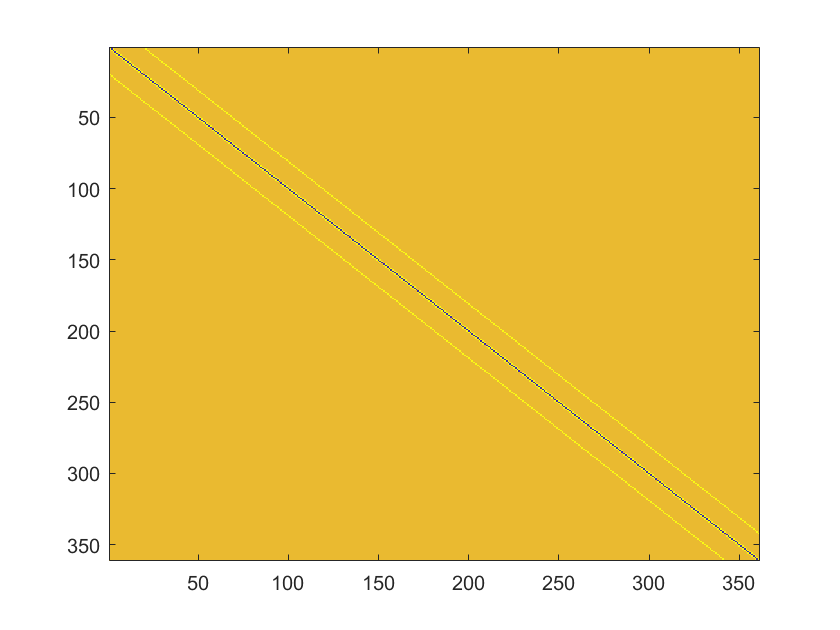

imagesc(A)

## vecteur cste C

temp=zeros(nbrOfPts-1);
for i=1:nbrOfPts-1
    for j=1:nbrOfPts-1
        temp(i,j)=(h^2)*f(i*h,j*h);
    end
end
temp

temp =    -0.4688   -1.1719   -2.3438   -3.9844   -6.0938   -8.6719  -11.7188  -15.2344  -19.2188  -23.6719  -28.5938  -33.9844  -39.8438  -46.1719  -52.9688  -60.2344  -67.9688  -76.1719  -84.8438
   -1.1719   -1.8750   -3.0469   -4.6875   -6.7969   -9.3750  -12.4219  -15.9375  -19.9219  -24.3750  -29.2969  -34.6875  -40.5469  -46.8750  -53.6719  -60.9375  -68.6719  -76.8750  -85.5469
   -2.3438   -3.0469   -4.2188   -5.8594   -7.9688  -10.5469  -13.5938  -17.1094  -21.0938  -25.5469  -30.4688  -35.8594  -41.7188  -48.0469  -54.8438  -62.1094  -69.8438  -78.0469  -86.7188
   -3.9844   -4.6875   -5.8594   -7.5000   -9.6094  -12.1875  -15.2344  -18.7500  -22.7344  -27.1875  -32.1094  -37.5000  -43.3594  -49.6875  -56.4844  -63.7500  -71.4844  -79.6875  -88.3594
   -6.0938   -6.7969   -7.9688   -9.6094  -11.7188  -14.2969  -17.3438  -20.8594  -24.8438  -29.2969  -34.2188  -39.6094  -45.4688  -51.7969  -58.5938  -65.8594  -73.5938  -81.7969  -90.4688
   -8.6719   -9.3750  -10.5469  -12.18

% 4 cote
temp(1,:)=temp(1,:)-Tcontour;
temp(:,1)=temp(:,1)-Tcontour;
temp(length(temp),:)=temp(length(temp),:)-Tcontour;
temp(:,length(temp))=temp(:,length(temp))-Tcontour;
temp

temp =   -56.4688  -29.1719  -30.3438  -31.9844  -34.0938  -36.6719  -39.7188  -43.2344  -47.2188  -51.6719  -56.5938  -61.9844  -67.8438  -74.1719  -80.9688  -88.2344  -95.9688 -104.1719 -140.8438
  -29.1719   -1.8750   -3.0469   -4.6875   -6.7969   -9.3750  -12.4219  -15.9375  -19.9219  -24.3750  -29.2969  -34.6875  -40.5469  -46.8750  -53.6719  -60.9375  -68.6719  -76.8750 -113.5469
  -30.3438   -3.0469   -4.2188   -5.8594   -7.9688  -10.5469  -13.5938  -17.1094  -21.0938  -25.5469  -30.4688  -35.8594  -41.7188  -48.0469  -54.8438  -62.1094  -69.8438  -78.0469 -114.7188
  -31.9844   -4.6875   -5.8594   -7.5000   -9.6094  -12.1875  -15.2344  -18.7500  -22.7344  -27.1875  -32.1094  -37.5000  -43.3594  -49.6875  -56.4844  -63.7500  -71.4844  -79.6875 -116.3594
  -34.0938   -6.7969   -7.9688   -9.6094  -11.7188  -14.2969  -17.3438  -20.8594  -24.8438  -29.2969  -34.2188  -39.6094  -45.4688  -51.7969  -58.5938  -65.8594  -73.5938  -81.7969 -118.4688
  -36.6719   -9.3750  -10.5469  -12.18

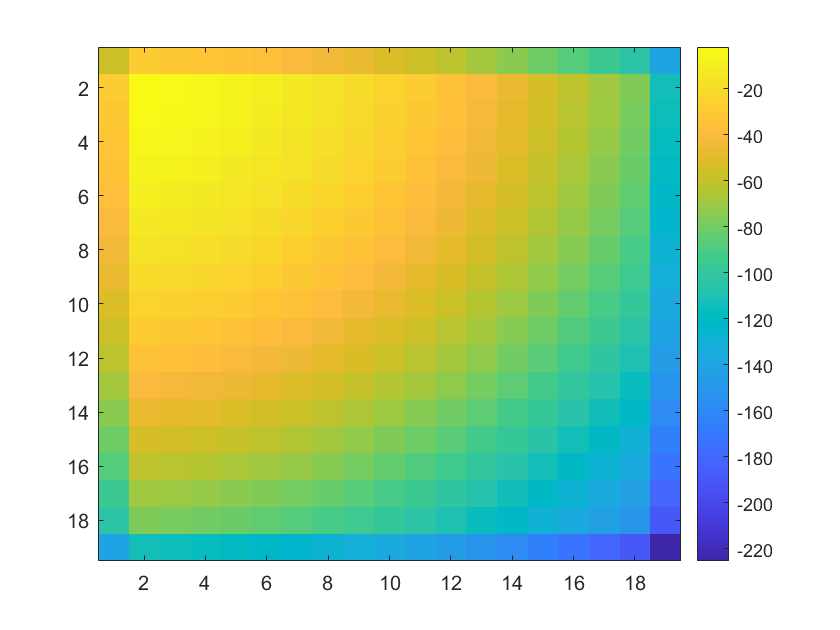

% 4 sommet
temp(1,1)=temp(1,1)-2*Tcontour;
temp(1,length(temp))=temp(1,length(temp))-2*Tcontour;
temp(length(temp),1)=temp(length(temp),1)-2*Tcontour;
temp(length(temp),length(temp))=temp(length(temp),length(temp))-2*Tcontour;
temp

imagesc(temp) %valeur de laplacien de chq pts inconnu
colorbar

C=zeros(length(temp)^2,1)

C =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=1:length(temp)
    C(1+(i-1)*length(temp):length(temp)+(i-1)*length(temp),1)=temp(i,:);
end
C

C =   -56.4688
  -29.1719
  -30.3438
  -31.9844
  -34.0938
  -36.6719
  -39.7188
  -43.2344
  -47.2188
  -51.6719


## vecteur Tvec

Tvec=A\C

Tvec = 	1.0e+03 *

    0.0540
    0.0797
    0.1052
    0.1304
    0.1553
    0.1796
    0.2033
    0.2259
    0.2472
    0.2666


## matrice final Z

Z=zeros(length(temp)+2)

Z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

for i=2:length(Z)-1
    Z(i, 2:length(Z)-1)=Tvec(1+(nbrOfPts-1)*(i-2):(nbrOfPts-1)+(nbrOfPts-1)*(i-2));
end

Z(1,:)=Tcontour;
Z(length(Z),:)=Tcontour;
Z(:,1)=Tcontour;
Z(:,length(Z))=Tcontour;
Z

Z = 	1.0e+03 *

    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280    0.0280
    0.0280    0.0540    0.0797    0.1052    0.1304    0.1553    0.1796    0.2033    0.2259    0.2472    0.2666    0.2835    0.2971    0.3063    0.3098    0.3059    0.2922    0.2654    0.2201    0.1474    0.0280
    0.0280    0.0797    0.1305    0.1804    0.2293    0.2770    0.3233    0.3678    0.4100    0.4491    0.4841    0.5138    0.5366    0.5505    0.5529    0.5406    0.5093    0.4531    0.3637    0.2285    0.0280
    0.0280    0.1052    0.1804    0.2535    0.3245    0.3933    0.4593    0.5222    0.5812    0.6351    0.6825    0.7217    0.7503    0.7656    0.7639    0.7407    0.6904    0.6054    0.4761    0.2894    0.0280
    0.0280    0.1304    0.2293    0.3245    0.4163    0.5042    0.5880    0.6671    0.7403    0.8064    0.8636    0.9096    0.9416    0.9559

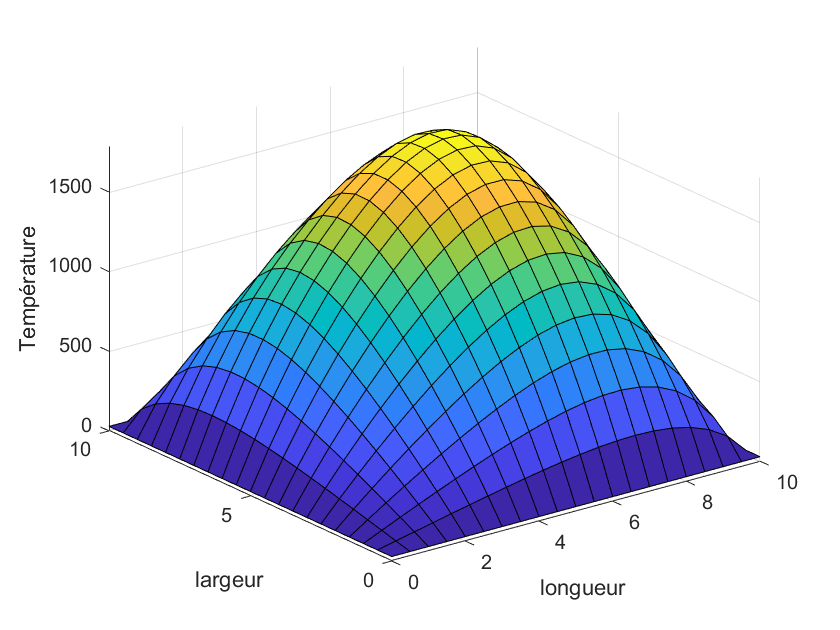

figure(1)
[xq,yq] = meshgrid(0:h:longueur, 0:h:longueur);
surfc(xq,yq,Z)
xlabel('longueur')
ylabel('largeur')
zlabel('Température')

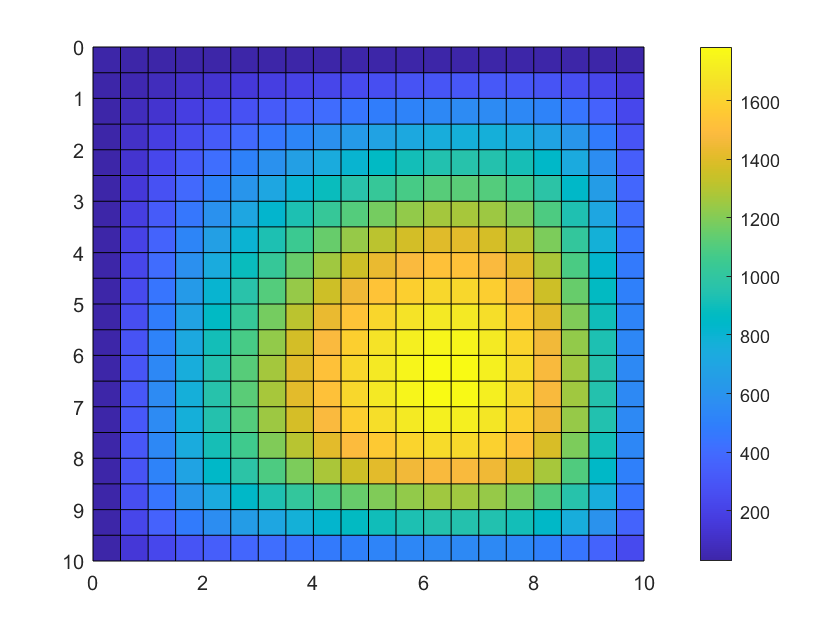


figure(2)
surf(xq,yq,Z)
view([90,90])
colorbar

## this part is no longer necessary


% figure(3)
% nbr_pts=5 % nbr de pts entre deux pts originaux
% accuracy=1/nbr_pts;
% [xqq,yqq] = meshgrid(0:accuracy:nbrOfPts, 0:accuracy:nbrOfPts); %précision d'interpolation
% vq = griddata(xq,yq,Z,xqq,yqq,'cubic')
% surf(xqq,yqq,vq)


